## Problem 9.2

$\hat{\mathbf{x}} ={\mathbf{A}}^{\dagger} \mathbf{b}={\left\lbrack \begin{array}{cccc}
0\ldotp 54 & 2\ldotp 4 & 3\ldotp 09 & 3\ldotp 73
\end{array}\right\rbrack }^T$, which is quite different from $\mathbf{x}={\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4
\end{array}\right\rbrack }^T$. In fact, the MSE $||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} ||_2^2 =0\ldotp 27$, despite the fact that $\textrm{Ax}=\mathbf{A}\hat{\mathbf{x}} =\mathbf{b}$. The matrix A is under-determined, so there are many solutions to $\textrm{Ax}=\mathbf{b}$.

A = [[1, 4, 5, 6]; [6, 7, 2, 1]];
b = [48, 30].';
[u, s, v] = svd(A);
A_dag = v(:, 1:2)*inv(s(:, 1:2))*u.';
x_hat = A_dag*b;
display(x_hat);

x_hat =     0.5442
    2.4027
    3.0929
    3.7301


x = [1 2 3 4].';
A*x_hat;
fprintf("MSE of x: %d", norm((x-x_hat).^2));

MSE of x: 2.735177e-01

## Problem 9.4

load("blocksdeconv2024.mat");

*Part A* - Write a function that take vector $\mathbf{h}$ and returns an MxN circulant matrix $\mathbf{A}$ such that for any $\mathbf{x}\in {\mathbb{R}}^N$,  $\textrm{Ax}$ is the vector of non-zero values of $\mathbf{h}$ convolved with $\mathbf{x}$

function A = generateCirculantMatrix(x, N)
    A = convmtx(x, N);
end

*Part B* - Find the SVD of $\mathbf{A}$. What are it's largest and smallest singular values? Calculate and plot ${\mathbf{A}}^{\dagger} \mathbf{y}$.

The largest singular value of $\mathbf{A}$is 0.9937.

The smallest singular value of $\mathbf{A}$ 0.0004.

See plot below:

A = generateCirculantMatrix(h, length(x));
[u, s, v] = svd(A);

A_dag = pinv(A);
x_hat = A_dag*y;
plot(x_hat);

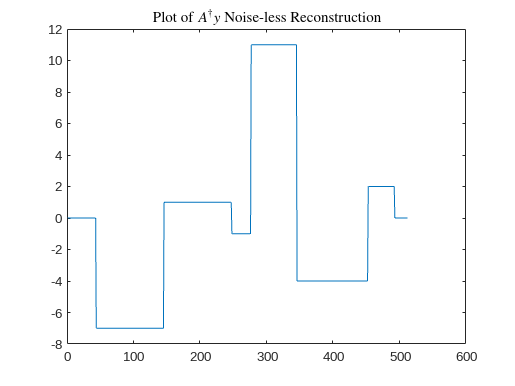

title("Plot of $A^\dag y$ Noise-less Reconstruction", 'Interpreter','latex');

fprintf("Largest SV: %d", max(s(:, 1)));

Largest SV: 9.993705e-01

fprintf("Smallest SV: %d", max(s(:, end)));

Smallest SV: 4.349731e-04

*Part C* - Apply ${\mathbf{A}}^{\dagger}$ to the noisy ${\mathbf{y}}_{\mathbf{n}}$. Plot it and calculare the mean-square error and compare it to the measurement error.


$$||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} |_2^2 =5217\ldotp 225$$



$$||\mathit{\mathbf{y}}-{\mathit{\mathbf{y}}}_{\mathit{\mathbf{n}}} ||_2^2 =0\ldotp 016$$


The MSE is more than 300,000 times more than the measurement error!

See plot below:

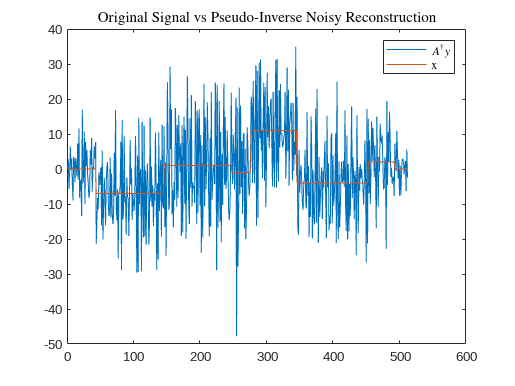

xn_hat = A_dag*yn;
p1 = plot(xn_hat); hold on;
p2 = plot(x); hold off;
title("Original Signal vs Pseudo-Inverse Noisy Reconstruction", 'Interpreter','latex');
legend([p1, p2], ["$A^\dag y$", "x"], 'Interpreter','latex');


fprintf("MSE of x: %d", norm((x-xn_hat).^2));

MSE of x: 5.217225e+03

fprintf("MSE of y: %d", norm((y-yn).^2));

MSE of y: 1.555198e-02

*Part D* - Form an approximation  by truncating the last q terms of the singular values. Which q minimizes MSE?

function y = svd_trunc(x, r)
    [U, S, V] = svd(x);
    y = U(:,1:r)*S(1:r,1:r)*V(:,1:r).';
end

Minimized $||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} |_2^2 =63\ldotp 5557$

q that minimizes $||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} |_2^2$: $q=379$

This minimization reduces the rank of $\mathbf{A}$ signficantly.

See plot of reconstructed signal.

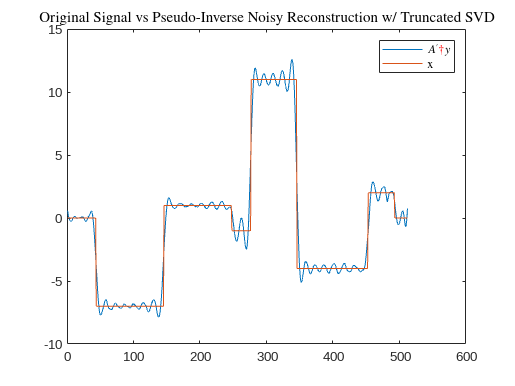

error = zeros(512, 1);
for q = 1:512
    A_trunc = svd_trunc(A, 512-q);
    error(q) = norm((x-pinv(A_trunc)*yn)).^2; 
end

[val, pos] = min(error);
A_trunc = svd_trunc(A, 512-pos);

p1 = plot(pinv(A_trunc)*yn); hold on;
p2 = plot(x); hold off;
title("Original Signal vs Pseudo-Inverse Noisy Reconstruction w/ Truncated SVD", 'Interpreter','latex');
legend([p1, p2], ["$A'^\dag y$", "x"], 'Interpreter','latex');

fprintf("q that minimizes MSE: %i", pos);

q that minimizes MSE: 440

fprintf("MSE is %d", val);

MSE is 3.929478e+02

*Part E *- Form another approximate inverse using Tikhonov Regularization. Try a number of values of $\delta$ which may minimize $||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} ||_2^2$. Calculate MSE.


$$||\mathit{\mathbf{x}}-\hat{\mathit{\mathbf{x}}} |_2^2 =63\ldotp 2332$$


$\delta =\;$0.000081818

See plot below:

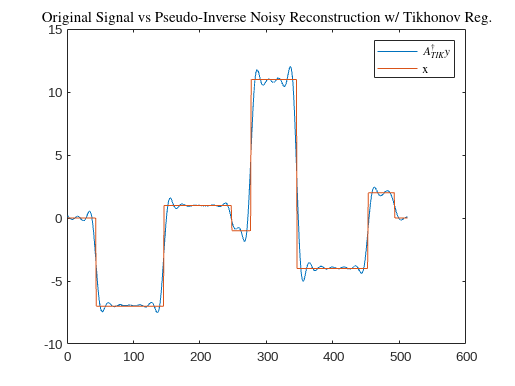

% This is the range of the minimum & was found experimentally
sigma = linspace(0, 0.0001, 100);
error = zeros(length(sigma), 1);
for i = 1:length(sigma)
    x_tik = (A.'*A+(sigma(i))*eye(512))\A.'*yn;
    error(i) = norm((x-x_tik)).^2;
end

[val, pos] = min(error);
x_tik = (A.'*A+0.01*eye(512))\A.'*yn;
p1 = plot(x_tik); hold on;
p2 = plot(x); hold off;
title("Original Signal vs Pseudo-Inverse Noisy Reconstruction w/ Tikhonov Reg.", 'Interpreter','latex');
legend([p1, p2], ["$A_{TIK}^\dag y$", "x"], 'Interpreter','latex');

fprintf("Sigma that minimizes MSE: %i", sigma(pos));

Sigma that minimizes MSE: 1.000000e-04

fprintf("MSE is %d", val);

MSE is 4.684648e+02

*Part F *- Summarize your findinfs by comparing MSE in parts c, d, and e. Compare to the error of doing nothing.

The MSE of simply performing the pseudo-inverse is orders of magnitude worse than the minimized MSE using the truncated SVD or tikhonov regularization. The MSE of optimal truncated SVD and Tikhonov regularization is functionally the same, though Tikhonov regularization was able to acheive a slightly smaller MSE.

While the plot of the ${\mathbf{y}}_{\mathbf{n}}$ vs $\mathbf{x}$ looks cleaner than the above plots, it's mean square error is 2 times worse than that of the methods in d and e. Doing nothing is, however, better than simply reconstructing with the pseudo-inverse. It also requires 0 computations.


$$||{\mathbf{y}}_{\mathbf{n}} -\hat{\mathbf{x}} ||_2^2 =128\ldotp 5728$$


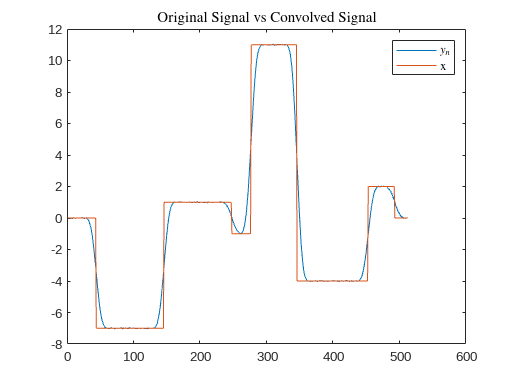

% Find error of doing nothing
offset = length(h) / 2;
yn_sig = yn(offset:end-offset);
p1 = plot(yn_sig); hold on;
p2 = plot(x); hold off;
title("Original Signal vs Convolved Signal", 'Interpreter','latex');
legend([p1, p2], ["$y_n$", "x"], 'Interpreter','latex');

fprintf("MSE of no reconstruction: %d", norm((x-yn_sig).^2));

MSE of no reconstruction: 1.285728e+02